## Minimum Time

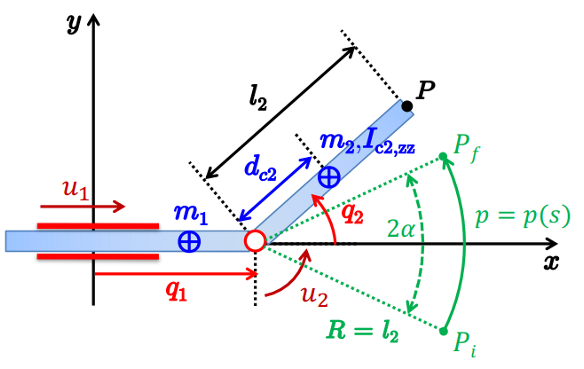

### Inertia Matrix - Gravity Terms - Christoffel Coefficients

syms q1 q2 dq1 dq2 m1 m2 l1 l2 I2 d1 d2 positive

% Joint 1
T1 = 0.5*m1*dq1^2

$$T1 = \frac{{{\mathrm{dq}}_{1}}^{2}\,m_{1}}{2}$$

U1 = 0;

% Joint 2
x2 = q1+d2*cos(q2);
y2 = d2*sin(q2);

vx2 = diff(x2, q1)*dq1 + diff(x2, q2)*dq2;
vy2 = diff(y2, q1)*dq1 + diff(y2, q2)*dq2;

T2_tr = 0.5*m2*[vx2 vy2]*[vx2; vy2;];
T2_rot = 0.5*I2*dq2^2;
T2 = T2_tr+T2_rot;
U2 = m2*g0*d2*sin(q2);

% Total Kinetic Energy
T=T1+T2

$$T = \frac{I_{2}\,{{\mathrm{dq}}_{2}}^{2}}{2}+\frac{{{\mathrm{dq}}_{1}}^{2}\,m_{1}}{2}+\frac{m_{2}\,{\left({\mathrm{dq}}_{1}-d_{2}\,{\mathrm{dq}}_{2}\,\sin\left(q_{2}\right)\right)}^{2}}{2}+\frac{{d_{2}}^{2}\,{{\mathrm{dq}}_{2}}^{2}\,m_{2}\,{\cos\left(q_{2}\right)}^{2}}{2}$$


% Inertia Matrix
M11 = diff(diff(T, dq1), dq1);
M12 = diff(diff(T, dq1), dq2);

M21 = diff(diff(T, dq2), dq1);
M22 = diff(diff(T, dq2), dq2);

M = [M11, M12;
     M21, M22;];

M = simplify(M);

disp('The inertia matrix M(q) is:');

The inertia matrix M(q) is:


disp(M);

$$\left(\begin{array}{cc} m_{1}+m_{2} & -d_{2}\,m_{2}\,\sin\left(q_{2}\right)\\ -d_{2}\,m_{2}\,\sin\left(q_{2}\right) & m_{2}\,{d_{2}}^{2}+I_{2} \end{array}\right)$$

### Gravity Terms


% Potential Energy and Gravity Terms
U = [U1+U2;];
g_q = simplify([diff(U,q1); diff(U,q2);], Steps=100);

disp('Potential Energy: ');

Potential Energy: 


disp(U);

$$d_{2}\,g_{0}\,m_{2}\,\sin\left(q_{2}\right)$$

disp('Gravity terms g(q): ');

Gravity terms g(q): 


disp(g_q);

$$\left(\begin{array}{c} 0\\ d_{2}\,g_{0}\,m_{2}\,\cos\left(q_{2}\right) \end{array}\right)$$

### Christoffel symbols


% using the Christoffel symbols for a 3-DOF system
q  = [q1; q2;];
dq = [dq1; dq2;];

% Inizializza la matrice C(q, dq) (3x3) a zeri simbolici:
C = sym(zeros(2,2));

% Formula dei coefficienti di Christoffel (Robotics):
%   C(i,j) = 1/2 * SUM_k [ dM(i,j)/dq_k + dM(i,k)/dq_j - dM(k,j)/dq_i ] * dq_k
% Poi il vettore c(q,dq) = C(q,dq) * dq
for i = 1:2
    for j = 1:2
        % Costruisco ogni elemento C(i,j):
        tmp = 0;
        for k = 1:2
            tmp = tmp + 0.5 * ( ...
                diff(M(i,j), q(k)) + ...
                diff(M(i,k), q(j)) - ...
                diff(M(k,j), q(i)) ) * dq(k);
        end
        C(i,j) = simplify(tmp);  % semplifico
    end
end

% Finalmente calcolo il vettore c(q, dq):
c_vec = simplify(C * dq);

disp('La matrice di Coriolis C(q,dq) è:');

La matrice di Coriolis C(q,dq) è:


disp(C);

$$\left(\begin{array}{cc} 0 & -d_{2}\,{\mathrm{dq}}_{2}\,m_{2}\,\cos\left(q_{2}\right)\\ 0 & 0 \end{array}\right)$$


disp('Il vettore c(q,dq) = C(q,dq)*dq è:');

Il vettore c(q,dq) = C(q,dq)*dq è:


disp(c_vec);

$$\left(\begin{array}{c} -d_{2}\,{{\mathrm{dq}}_{2}}^{2}\,m_{2}\,\cos\left(q_{2}\right)\\ 0 \end{array}\right)$$

### Utils for ex

p = [q1+l2*cos(q2); l2*sin(q2);];
p_dot = [diff(p(1),q1)*dq1+diff(p(1),q2)*dq2;
         diff(p(2),q1)*dq1+diff(p(2),q2)*dq2]

$$p\_dot = \left(\begin{array}{c} {\mathrm{dq}}_{1}-{\mathrm{dq}}_{2}\,l_{2}\,\sin\left(q_{2}\right)\\ {\mathrm{dq}}_{2}\,l_{2}\,\cos\left(q_{2}\right) \end{array}\right)$$

p_dot_dot = [diff(p_dot(1),q1)*dq1+diff(p_dot(1),q2)*dq2;
             diff(p_dot(2),q1)*dq1+diff(p_dot(2),q2)*dq2]

$$p\_dot\_dot = \left(\begin{array}{c} -{{\mathrm{dq}}_{2}}^{2}\,l_{2}\,\cos\left(q_{2}\right)\\ -{{\mathrm{dq}}_{2}}^{2}\,l_{2}\,\sin\left(q_{2}\right) \end{array}\right)$$

J = jacobian(p, [q1,q2])

$$J = \left(\begin{array}{cc} 1 & -l_{2}\,\sin\left(q_{2}\right)\\ 0 & l_{2}\,\cos\left(q_{2}\right) \end{array}\right)$$